# Using NWB Data

*Lawrence Niu (lawrence@vidriotech.com)*

*last updated: June 4, 2019*

In this tutorial, we create a raster map of spikes using the converted NWB file in the [File Conversion Tutorial](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/convertTrials.html).

Reading the conversion tutorial is unnecessary for this tutorial if one only requires reading from NWB data.

## Reading NWB Files

NWB files can be read in using the *nwbRead()* function.  This function returns a *nwbfile* object which is the in-memory representation of the NWB file structure.

nwb = nwbRead('out\ANM255201_20141124.nwb');

## **Constrained Sets**

Analyzed data in NWB is placed under the *analysis* property, which is a **Constrained Set**.  A constrained set consists of an arbitrary amount of key-value pairs similar to a *containers.Map* in MATLAB or a dictionary in Python.  However, constrained sets also have the ability to validate their own properties closer to how a typed Object would.

You can get/set values in constrained sets using their respective *.get()/.set()* methods and retrieve all Set properties using the *keys() *method, like in a *containers.Map.*

unit_names = keys(nwb.analysis);

## Dynamic Tables

*nwb.intervals_trials* returns a unique type of table called a **Dynamic Table**.  Dynamic tables inherit from the NWB type *types.core.DynamicTable* and allow for a table-like interface in NWB.  In the case below, we grab the special column *start_time*.  Dynamic Tables allow adding your own vectors using their *vectordata* and *vectorindex* properties, which are Constrained Sets.  All columns are represented by either a *types.core.VectorData *or a *types.core.VectorIndex* type.

## Data Stubs

The *data* property of the column *start_time* is a *types.untyped.DataStub.*  This object is a representation of an unloaded dataset, and is what allows MatNWB to lazily load its file data.  To load the data into memory, use the *.load() *method which extracts the data from the NWB file*.*

trial_start_time = nwb.intervals_trials.start_time.data.load();
trials = nwb.intervals_trials.vectordata;
trial_lick_right = trials.get('HitR').data.load();
trial_lick_left = trials.get('HitL').data.load();
trial_sample = trials.get('PoleInTime').data.load();
trial_delay = trials.get('PoleOutTime').data.load();
trial_response = trials.get('CueTime').data.load();
trial_good_trials = trials.get('GoodTrials').data.load();
trial_is_photostim = trials.get('StimTrials').data.load();
trial_photostim_type = trials.get('PhotostimulationType').data.load();
% photostim type can be found under the PhotostimulationType description
trial_is_no_stim = ~trial_is_photostim & trial_photostim_type == 0;
trial_is_sample_stim = trial_is_photostim & trial_photostim_type == 1;
trial_is_early_delay_stim = trial_is_photostim & trial_photostim_type == 2;
trial_is_middle_delay_stim = trial_is_photostim & trial_photostim_type == 3;

## Jagged Arrays

All data in a Dynamic Table must be aligned by row and column, but not all data fits into this paradigm neatly.  In order to represent variable amounts of data that is localised to each row and column, NWB uses a concept called **Jagged Arrays**.  These arrays consist of two column types: the familiar *types.core.VectorData*, and the new *types.core.VectorIndex*.  A Vector Index holds no data, instead holding a reference to another Vector Data and a vector of indices that align to the Dynamic Table dimensions.  The indices represent the last index boundary in the Vector Data object for the Vector Index row.  As an example, an index of three in the first row of the Vector Index column points to the first three values in the referenced Vector Data column.  Subsequently, if the next index were a five, it would indicate the fourth and fifth elements in the referenced Vector Data column.

Below, *unit_trial* and *unit_times* are jagged arrays which must be referenced by a respective *unit_trial_idx* and *unit_times_idx* index array.

unit_trials_data = nwb.units.vectordata.get('trials').data.load();
unit_trials_idx = nwb.units.vectorindex.get('trials_index').data.load();
unit_times_data = nwb.units.spike_times.data.load();
unit_times_idx = nwb.units.spike_times_index.data.load();
unit_ids = nwb.units.id.data.load();

As this format isn't terribly intuitive in MATLAB, we convert it to a cell array of matrices.

unit_trials = cell(size(unit_trials_idx));
unit_trials{1} = unit_trials_data(1:unit_trials_idx(1));
for i=2:length(unit_trials_idx)
    start_idx = unit_trials_idx(i-1) + 1;
    end_idx = unit_trials_idx(i);
    unit_trials{i} = unit_trials_data(start_idx:end_idx);
end

unit_times = cell(size(unit_times_idx));
unit_times{1} = unit_times_data(1:unit_times_idx(1));
for i=2:length(unit_times_idx)
    start_idx = unit_times_idx(i-1) + 1;
    end_idx = unit_times_idx(i);
    unit_times{i} = unit_times_data(start_idx:end_idx);
end

We now do the following for each Unit:

- Filter out invalid trials

- Separate datasets based on resulting mouse behavior (right/left licks).

- Derive "sample", "delay", and "response" times for this analyzed neuron.

- Compose a peristimulus time histogram from the data.


sorted_ids = sort(unit_ids);
Photostim = struct(...
    'ind', true,... % mask into xs and ys for this photostim
    'period', 'none',...
    'duration', 0,... % in seconds
    'ramp_offset', 0); % in seconds
Unit = struct(...
    'id', num2cell(sorted_ids),...
    'xs', [],...
    'ys', [],...
    'xlim', [-Inf Inf],...
    'sample', 0,...
    'delay', 0,...
    'response', 0,...
    'left_scatter', false,...
    'right_scatter', false,...
    'photostim', Photostim); % can have multiple photostim

for i=1:length(sorted_ids)

We first extract trial IDs from the Unit IDs.

    unit_idx = Unit(i).id == unit_ids;
    unit_trial_id = unit_trials{unit_idx};
    unit_good_trials = logical(trial_good_trials(unit_trial_id));

Then filter out outliers from the Sample, Delay, and Response time points with which we derive a "good enough" estimate.

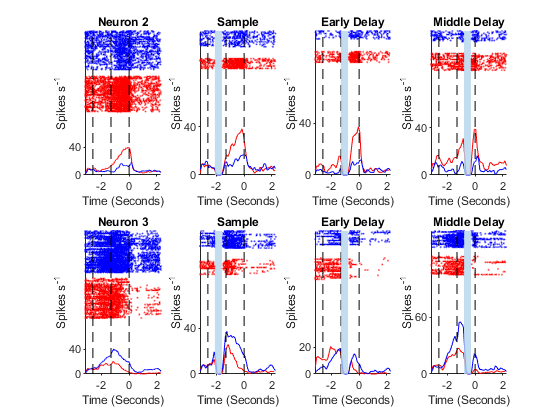

    unit_sample = trial_sample(unit_trial_id);
    unit_delay = trial_delay(unit_trial_id);
    unit_response = trial_response(unit_trial_id);
    % arbitrarily hardcoded.  Dependent on human error.
    delay_threshold = 0.064;
    response_threshold = 0.43;
    expected_delay_offset = 1.3; % derived from figure 1a
    expected_response_offset = 1.3;
    expected_delay = unit_sample + expected_delay_offset;
    expected_response = unit_delay + expected_response_offset;
    good_delay = (unit_delay > expected_delay - delay_threshold) &...
        (unit_delay < expected_delay + delay_threshold);
    good_response = (unit_response > expected_response - response_threshold) &...
        (unit_response < expected_response + response_threshold);
    avg_sample = mean(unit_sample(good_delay & good_response));
    avg_delay = mean(unit_delay(good_delay & good_response));
    avg_response = mean(unit_response(good_delay & good_response));

Filter the rest of the data by "good" trials.

    unit_good_trials = unit_good_trials & good_delay & good_response;
    
    unit_trial_id = unit_trial_id(unit_good_trials);
    
    unit_spike_time = unit_times{unit_idx};
    unit_spike_time = unit_spike_time(unit_good_trials);

Map the Trial-aligned data to Unit-aligned data.

    unit_lick_right = logical(trial_lick_right(unit_trial_id));
    unit_lick_left = logical(trial_lick_left(unit_trial_id));
    unit_start_time = trial_start_time(unit_trial_id);
    unit_stim_type = trial_photostim_type(unit_trial_id);
    unit_sample_stim = trial_is_sample_stim(unit_trial_id);
    unit_early_stim = trial_is_early_delay_stim(unit_trial_id);
    unit_middle_stim = trial_is_middle_delay_stim(unit_trial_id);
    unit_no_stim = trial_is_no_stim(unit_trial_id);

Compose Scatter Plots and the Peristimulus Time Histogram zeroed on the Response time.

    xs = unit_spike_time - unit_start_time - avg_response;
    ys = unit_trial_id;
    
    Unit(i).xs = xs;
    Unit(i).ys = ys;
    Unit(i).left_scatter = unit_lick_left;
    Unit(i).right_scatter = unit_lick_right;
    Unit(i).sample = avg_sample - avg_response;
    Unit(i).delay = avg_delay - avg_response;
    Unit(i).response = 0;
    
    % Photostim periods
    Unit(i).photostim.ind = unit_no_stim;
    
    % Sample
    if any(unit_sample_stim)
        SampleStim = Photostim;
        SampleStim.ind = unit_sample_stim;
        SampleStim.period = 'Sample';
        SampleStim.duration = 0.5;
        SampleStim.ramp_offset = 0.1;
        Unit(i).photostim(end+1) = SampleStim;
    end
    
    % Early Delay
    if any(unit_early_stim)
        early_stim_types = unique(unit_stim_type(unit_early_stim));
        for i_early_types=1:length(early_stim_types)
            early_type = early_stim_types(i_early_types);
            EarlyStim = Photostim;
            EarlyStim.period = 'Early Delay';
            EarlyStim.ind = early_type == unit_stim_type & unit_early_stim;
            if early_type == 2
                EarlyStim.duration = 0.5;
                EarlyStim.ramp_offset = 0.1;
            else
                EarlyStim.duration = 0.8;
                EarlyStim.ramp_offset = 0.2;
            end
            Unit(i).photostim(end+1) = EarlyStim;
        end
    end
    
    % Middle Delay
    if any(unit_middle_stim)
        MiddleStim = Photostim;
        MiddleStim.ind = unit_middle_stim;
        MiddleStim.period = 'Middle Delay';
        MiddleStim.duration = 0.5;
        MiddleStim.ramp_offset = 0.1;
        Unit(i).photostim(end+1) = MiddleStim;
    end
end

neuron_ids = [11, 2];
neuron_labels = [2, 3];
num_columns = 4; % nostim, sample, early, middle if applicable
num_rows = length(neuron_ids);
Plot = struct(...
    'xs', 0,...
    'ys', 0);
NeuronPlot = struct(...
    'label', '',...
    'xlim', 0,...
    'sample', 0,...
    'delay', 0,...
    'response', 0,...
    'right_scatter', Plot,...
    'left_scatter', Plot,...
    'psth_bin_window', 0,...
    'stim_type', '');
fig = figure;

for i_id=1:num_rows
    Neuron = Unit([Unit.id] == neuron_ids(i_id));
    i_row = (i_id - 1) * num_columns;
    
    StimPlot = NeuronPlot;
    StimPlot.xlim = [min(Neuron.xs) max(Neuron.xs)];
    StimPlot.sample = Neuron.sample;
    StimPlot.delay = Neuron.delay;
    StimPlot.response = Neuron.response;
    
    for i_stim=1:length(Neuron.photostim)
        ax = subplot(num_rows, num_columns, i_row + i_stim, 'Parent', fig);
        Stim = Neuron.photostim(i_stim);
        
        StimPlot.stim_type = Stim.period;
        if strcmp(Stim.period, 'none')
            StimPlot.label = sprintf('Neuron %d', neuron_labels(i_id));
            StimPlot.psth_bin_window = 9;
        else
            StimPlot.label = Stim.period;
            StimPlot.psth_bin_window = 2;
        end
        
        stim_left_scatter_ind = Stim.ind & Neuron.left_scatter;
        stim_left_scatter_trials = Neuron.ys(stim_left_scatter_ind);
        
        StimPlot.left_scatter.xs = Neuron.xs(stim_left_scatter_ind);
        [~,StimPlot.left_scatter.ys] = ismember(stim_left_scatter_trials,unique(stim_left_scatter_trials));
        
        stim_right_scatter_ind = Stim.ind & Neuron.right_scatter;
        stim_right_scatter_trials = Neuron.ys(stim_right_scatter_ind);
        
        StimPlot.right_scatter.xs = Neuron.xs(stim_right_scatter_ind);
        [~,StimPlot.right_scatter.ys] = ismember(stim_right_scatter_trials,unique(stim_right_scatter_trials));
        
        plot_neuron(ax, StimPlot);
    end
end

PSTH helper function

function [psth_xs, psth_ys] = calculate_psth(xs, bin_window, bin_width)
[bin_counts, edges]  = histcounts(xs, 'BinWidth', bin_width);
psth_xs = edges(1:end-1) + (bin_width / 2);

moving_avg_b = (1/bin_window) * ones(1,bin_window);
psth_ys = filter(moving_avg_b, 1, bin_counts);
end

Neuron Plotter Function

function plot_neuron(ax, NeuronPlot)
left_cdata = [1 0 0]; % red
right_cdata = [0 0 1]; % blue
hist_margin = 50;
scatter_margin = 10;

% Calculate PSTH values
% moving average over 200 ms as per figure 1e
hist_bin_width = 0.2 / NeuronPlot.psth_bin_window;
[left_psth_xs, left_psth_ys] =...
    calculate_psth(NeuronPlot.left_scatter.xs, NeuronPlot.psth_bin_window, hist_bin_width);
[right_psth_xs, right_psth_ys] =...
    calculate_psth(NeuronPlot.right_scatter.xs, NeuronPlot.psth_bin_window, hist_bin_width);

right_scatter_offset = min(NeuronPlot.right_scatter.ys);
right_scatter_height = max(NeuronPlot.right_scatter.ys) - right_scatter_offset;
left_scatter_offset = min(NeuronPlot.left_scatter.ys);
left_scatter_height = max(NeuronPlot.left_scatter.ys) - left_scatter_offset;
psth_height = max([left_psth_ys right_psth_ys]);

left_y_offset = hist_margin...
    + psth_height...
    - left_scatter_offset;

right_y_offset = scatter_margin...
    + left_y_offset...
    + left_scatter_offset...
    + left_scatter_height...
    - right_scatter_offset;

subplot_height = right_y_offset...
    + right_scatter_offset...
    + right_scatter_height;

hold(ax, 'on');

% PSTH
plot(ax, left_psth_xs, left_psth_ys, 'Color', left_cdata);
plot(ax, right_psth_xs, right_psth_ys, 'Color', right_cdata);

% Scatter Plot
scatter_left_plot = scatter(ax,...
    NeuronPlot.left_scatter.xs,...
    left_y_offset + NeuronPlot.left_scatter.ys,...
    'Marker', '.',...
    'CData', left_cdata,...
    'SizeData', 1);
scatter_right_plot = scatter(ax,...
    NeuronPlot.right_scatter.xs,...
    right_y_offset + NeuronPlot.right_scatter.ys,...
    'Marker', '.',...
    'CData', right_cdata,...
    'SizeData', 1);

% sample, delay, response lines
line(ax, repmat(NeuronPlot.sample, 1, 2), [0 subplot_height],...
    'Color', 'k', 'LineStyle', '--');
line(ax, repmat(NeuronPlot.delay, 1, 2), [0 subplot_height],...
    'Color', 'k', 'LineStyle', '--');
line(ax, repmat(NeuronPlot.response, 1, 2), [0 subplot_height],...
    'Color', 'k', 'LineStyle', '--');

% photoinhibition period
if ~strcmp(NeuronPlot.stim_type, 'none')
    stim_height = subplot_height;
    stim_width = 0.5; % seconds
    % end time relative to 'go' cue as described in the paper.
    switch NeuronPlot.stim_type
        case 'Sample'
            end_offset = 1.6;
        case 'Early Delay'
            end_offset = 0.8;
        case 'Middle Delay'
            end_offset = 0.3;
        otherwise
            error('Invalid photostim period `%s`', NeuronPlot.stim_type);
    end
    stim_offset = NeuronPlot.response - stim_width - end_offset;
    patch_vertices = [...
        stim_offset, 0;...
        stim_offset, stim_height;...
        stim_offset+stim_width, stim_height;...
        stim_offset+stim_width, 0];
    patch(ax,...
        'Faces', 1:4,...
        'Vertices', patch_vertices,...
        'FaceColor', '#B3D3EC',...
        'EdgeColor', 'none',...
        'FaceAlpha', 0.8);
end

title(ax, NeuronPlot.label);
xlabel(ax, 'Time (Seconds)');
ylabel(ax, 'Spikes s^{-1}')
xticks(ax, [-2 0 2]);
yticks(ax, [0 max(10, round(psth_height, -1))]);
%     legend(ax, [scatter_left_plot, scatter_right_plot], {'Left Lick', 'Right Lick'},...
%         'location', 'northwestoutside');
ax.TickDir = 'out';
ax.XLim = NeuronPlot.xlim;
ax.YLim = [0 subplot_height];

hold(ax, 'off');
end